# A Estimation curve VS different S_EI:L6 added

## first, setup connctivity map

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

load('NtWk_Archit.mat')

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.5;  
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

## Network Simulation

%% Network Simulation
T = 3000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.3; N_EEDly = floor(T_EEDly/dt);
% Setup Results Recording
Fr_NW_BG      = zeros(2,1);
mV_NW_BG      = zeros(2,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

% Compute Neuron Ind
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);

I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2));
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

% Create sliding windows
sampleT = 200;
Sliding = 100;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
InSs = load('Initials_L6.mat');
RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);

%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
    'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver2_EEDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        C_EE,C_EI,C_IE,C_II,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_amb,lambda_E,lambda_I,rE_amb,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
            ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
            'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
            ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
            'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        fprintf(ParameterDisp)
        h = figure('Name','TestRaster');
        subplot 311
        hist(oVE,-0.3:0.02:1)
        title(['mVE = ' num2str(nanmean(VE_T))])
        %E_SpHis = [E_SpHis,sum(oSpE)];
        %axis([-0.4 1.1 0 6000])
        
        subplot 312
        hist(oVI,-0.3:0.02:1)
        title(['mVI = ' num2str(nanmean(VI_T))])
              
        %E_Ind = 10000:13000; I_Ind = 3300:4300;
        scatterE = find(ismember(E_Sp(:,1),E_Ind));
        scatterI = find(ismember(I_Sp(:,1),I_Ind));
        [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
        [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
        
        WinSize = SimulationT;
        T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        
        f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    S_EL6,S_IL6,rE_L6,rI_L6,...
                                                    gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));
        %
        subplot 313
        hold on
        scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
        scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
        title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
        xlabel('Time (ms)')
        xlim(T_RateWindow)
        ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
        drawnow
        %pause
        close(h)
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(E_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(E_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
        toc
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
    if sum(isnan(oVE))>0.80*N_E
        BlowUp = true;
        disp('warning!: Network exploded')
        break
    end
    
    % the end of iteration
end

Elapsed time is 5.536615 seconds.
Elapsed time is 8.323039 seconds.
Elapsed time is 11.124457 seconds.
Elapsed time is 13.979916 seconds.
Elapsed time is 16.768171 seconds.
Elapsed time is 19.654742 seconds.
Elapsed time is 22.424990 seconds.
Elapsed time is 25.256532 seconds.


S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

Elapsed time is 29.728347 seconds.
Elapsed time is 32.684791 seconds.
Elapsed time is 35.438670 seconds.
Elapsed time is 38.424737 seconds.
Elapsed time is 41.332311 seconds.
Elapsed time is 44.323996 seconds.
Elapsed time is 47.424519 seconds.
Elapsed time is 50.580756 seconds.
Elapsed time is 53.797057 seconds.
Elapsed time is 56.915432 seconds.


S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

Elapsed time is 60.397897 seconds.
Elapsed time is 63.637736 seconds.
Elapsed time is 66.931659 seconds.
Elapsed time is 70.142332 seconds.
Elapsed time is 73.574749 seconds.
Elapsed time is 77.093033 seconds.
Elapsed time is 80.627599 seconds.
Elapsed time is 84.137469 seconds.
Elapsed time is 87.787297 seconds.
Elapsed time is 91.418897 seconds.


S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

Elapsed time is 95.344352 seconds.


toc

Elapsed time is 95.348192 seconds.



NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% If blown up, discard other recordings...
if ~BlowUp
    Fr_NW_BG     = [E_Rate;I_Rate];
    mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
    %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
end
% end of S_IE loop



## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_E = zeros(size(NnE.X),'single');
OD_EMap = zeros(n_E_HC*N_HC,'single');
for NeuInd = 1:length(NnE.X)
OD_E(NeuInd) = OrientDom(ODNum,NnE.X(NeuInd),NnE.Y(NeuInd),n_E_HC);
OD_EMap(NnE.Y(NeuInd),NnE.X(NeuInd)) = OD_E(NeuInd);
end

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lgnE_Drive = [60,50,42,50]*4/1e3;
lgnI_Drive = min(lgnE_Drive);
lambda_E_drive = lgnE_Drive(OD_E)';
lambda_I_drive = lgnI_Drive;

L6E_Drive = [50 35 20 35]*50/1e3;
L6I_Drive = min(L6E_Drive);
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';


% Making Poisson here/Reading
T = 10000; dt = 0.1;
TimeFrac = 0.05;
LGNCurInp = 0.3;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0.8;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);

%   [A,~,Times] = find(eventsN);
%   R = sparse(A,floor(Times/dt)+1,ones(size(A)),N,length(t));

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
SimulationT = 5000; 
% E-to-E delay time
T_EEDly = 1; N_EEDly = floor(T_EEDly/dt);

% % The initial states
% InSs = load('Initials_L6.mat');
% RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
% GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
% RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
% GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
% EEDlyRcd = sparse(N_E,N_EEDly);

% The initial states, for more simulation
load('DriveWkSp_10.mat','EndState');
RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
                                                             GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
RefTimeI = EndState{10}; VI = EndState{11}; SpI = EndState{12}; GI_ampa_R = EndState{13}; GI_nmda_R = EndState{14}; GI_gaba_R = EndState{15};
                                                                GI_ampa_D = EndState{16}; GI_nmda_D = EndState{17}; GI_gaba_D = EndState{18};
EEDlyRcd = EndState{19};

% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

But to accelerate, we exclude L6 Current Input at first...

TPar = 10;
for TSec = 11:TPar+10
tic
for TimeN = 1:floor(T/dt/TPar)
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) + lambda_E_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                      + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                      + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
     
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
          V1NetworkUpdate_Ver3_Drive_PoissonRead(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                          GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                          RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                          GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                          EEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE,C_EI,C_IE,C_II,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd;
    
     
    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.02;
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs= I_Sp;
              
        SampleInd = SampleInd + 1
        sum(isnan(oVE))/N_E
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
text = ['DriveWkSp_' num2str(TSec) '.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd};
save(text,'NWTrace','EndState','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
end

SampleInd = 2

ans = 0.0506

Elapsed time is 2.929628 seconds.


SampleInd = 3

ans = 0.0328

Elapsed time is 5.148704 seconds.


SampleInd = 4

ans = 0.0361

Elapsed time is 7.565353 seconds.


SampleInd = 5

ans = 0.0517

Elapsed time is 9.855231 seconds.


SampleInd = 6

ans = 0.0355

Elapsed time is 12.623412 seconds.


SampleInd = 7

ans = 0.0352

Elapsed time is 14.483150 seconds.


SampleInd = 8

ans = 0.0445

Elapsed time is 17.085736 seconds.


SampleInd = 9

ans = 0.0468

Elapsed time is 19.472478 seconds.


SampleInd = 10

ans = 0.0355

Elapsed time is 22.118390 seconds.


SampleInd = 11

ans = 0.0363

Elapsed time is 24.059414 seconds.


SampleInd = 12

ans = 0.0503

Elapsed time is 26.594973 seconds.


SampleInd = 13

ans = 0.0398

Elapsed time is 28.752322 seconds.


SampleInd = 14

ans = 0.0316

Elapsed time is 31.240172 seconds.


SampleInd = 15

ans = 0.0420

Elapsed time is 33.271525 seconds.


SampleInd = 16

ans = 0.0465

Elapsed time is 35.983516 seconds.


SampleInd = 17

ans = 0.0361

Elapsed time is 38.098743 seconds.


SampleInd = 18

ans = 0.0413

Elapsed time is 40.530141 seconds.


SampleInd = 19

ans = 0.0508

Elapsed time is 42.792660 seconds.


SampleInd = 20

ans = 0.0399

Elapsed time is 45.495970 seconds.


SampleInd = 21

ans = 0.0345

Elapsed time is 47.537121 seconds.


Elapsed time is 47.537884 seconds.


SampleInd = 22

ans = 0.0450

Elapsed time is 2.560539 seconds.


SampleInd = 23

ans = 0.0492

Elapsed time is 4.891690 seconds.


SampleInd = 24

ans = 0.0348

Elapsed time is 7.588626 seconds.


SampleInd = 25

ans = 0.0341

Elapsed time is 9.600626 seconds.


SampleInd = 26

ans = 0.0480

Elapsed time is 12.234556 seconds.


SampleInd = 27

ans = 0.0480

Elapsed time is 14.661579 seconds.


SampleInd = 28

ans = 0.0341

Elapsed time is 17.241177 seconds.


SampleInd = 29

ans = 0.0369

Elapsed time is 19.219141 seconds.


SampleInd = 30

ans = 0.0488

Elapsed time is 21.860721 seconds.


SampleInd = 31

ans = 0.0406

Elapsed time is 24.242285 seconds.


SampleInd = 32

ans = 0.0354

Elapsed time is 26.766067 seconds.


SampleInd = 33

ans = 0.0389

Elapsed time is 28.825669 seconds.


SampleInd = 34

ans = 0.0477

Elapsed time is 31.552761 seconds.


SampleInd = 35

ans = 0.0393

Elapsed time is 33.850696 seconds.


SampleInd = 36

ans = 0.0337

Elapsed time is 36.303694 seconds.


SampleInd = 37

ans = 0.0439

Elapsed time is 38.387508 seconds.


SampleInd = 38

ans = 0.0428

Elapsed time is 41.113014 seconds.


SampleInd = 39

ans = 0.0373

Elapsed time is 43.287038 seconds.


SampleInd = 40

ans = 0.0351

Elapsed time is 45.721650 seconds.


SampleInd = 41

ans = 0.0467

Elapsed time is 47.926713 seconds.


Elapsed time is 47.927438 seconds.


SampleInd = 42

ans = 0.0474

Elapsed time is 2.804277 seconds.


SampleInd = 43

ans = 0.0312

Elapsed time is 4.946844 seconds.


SampleInd = 44

ans = 0.0384

Elapsed time is 7.334676 seconds.


SampleInd = 45

ans = 0.0499

Elapsed time is 9.557659 seconds.


SampleInd = 46

ans = 0.0404

Elapsed time is 12.364016 seconds.


SampleInd = 47

ans = 0.0313

Elapsed time is 14.364359 seconds.


SampleInd = 48

ans = 0.0417

Elapsed time is 16.740473 seconds.


SampleInd = 49

ans = 0.0540

Elapsed time is 19.144523 seconds.


SampleInd = 50

ans = 0.0373

Elapsed time is 21.841966 seconds.


SampleInd = 51

ans = 0.0320

Elapsed time is 23.735291 seconds.


SampleInd = 52

ans = 0.0477

Elapsed time is 26.288021 seconds.


SampleInd = 53

ans = 0.0495

Elapsed time is 28.800432 seconds.


SampleInd = 54

ans = 0.0240

Elapsed time is 31.297484 seconds.


SampleInd = 55

ans = 0.0391

Elapsed time is 33.163266 seconds.


SampleInd = 56

ans = 0.0511

Elapsed time is 35.917759 seconds.


SampleInd = 57

ans = 0.0417

Elapsed time is 38.225132 seconds.


SampleInd = 58

ans = 0.0310

Elapsed time is 40.680748 seconds.


SampleInd = 59

ans = 0.0476

Elapsed time is 42.780021 seconds.


SampleInd = 60

ans = 0.0511

Elapsed time is 45.730115 seconds.


SampleInd = 61

ans = 0.0261

Elapsed time is 47.812462 seconds.


Elapsed time is 47.813187 seconds.


SampleInd = 62

ans = 0.0391

Elapsed time is 2.304609 seconds.


SampleInd = 63

ans = 0.0625

Elapsed time is 4.833751 seconds.


SampleInd = 64

ans = 0.0295

Elapsed time is 7.669625 seconds.


SampleInd = 65

ans = 0.0265

Elapsed time is 9.381618 seconds.


SampleInd = 66

ans = 0.0545

Elapsed time is 11.921395 seconds.


SampleInd = 67

ans = 0.0495

Elapsed time is 14.576759 seconds.


SampleInd = 68

ans = 0.0224

Elapsed time is 16.971646 seconds.


SampleInd = 69

ans = 0.0418

Elapsed time is 18.761272 seconds.


SampleInd = 70

ans = 0.0681

Elapsed time is 21.799244 seconds.


SampleInd = 71

ans = 0.0254

Elapsed time is 24.141417 seconds.


SampleInd = 72

ans = 0.0276

Elapsed time is 26.249931 seconds.


SampleInd = 73

ans = 0.0560

Elapsed time is 28.480822 seconds.


SampleInd = 74

ans = 0.0491

Elapsed time is 31.479908 seconds.


SampleInd = 75

ans = 0.0261

Elapsed time is 33.375965 seconds.


SampleInd = 76

ans = 0.0440

Elapsed time is 35.676236 seconds.


SampleInd = 77

ans = 0.0567

Elapsed time is 38.088316 seconds.


SampleInd = 78

ans = 0.0325

Elapsed time is 40.772332 seconds.


SampleInd = 79

ans = 0.0362

Elapsed time is 42.718884 seconds.


SampleInd = 80

ans = 0.0510

Elapsed time is 45.477893 seconds.


SampleInd = 81

ans = 0.0497

Elapsed time is 48.029326 seconds.


Elapsed time is 48.030081 seconds.


SampleInd = 82

ans = 0.0290

Elapsed time is 2.510325 seconds.


SampleInd = 83

ans = 0.0391

Elapsed time is 4.493900 seconds.


SampleInd = 84

ans = 0.0522

Elapsed time is 7.343450 seconds.


SampleInd = 85

ans = 0.0358

Elapsed time is 9.653999 seconds.


SampleInd = 86

ans = 0.0327

Elapsed time is 12.025237 seconds.


SampleInd = 87

ans = 0.0569

Elapsed time is 14.297827 seconds.


SampleInd = 88

ans = 0.0442

Elapsed time is 17.177418 seconds.


SampleInd = 89

ans = 0.0320

Elapsed time is 19.206924 seconds.


SampleInd = 90

ans = 0.0385

Elapsed time is 21.632175 seconds.


SampleInd = 91

ans = 0.0565

Elapsed time is 24.069670 seconds.


SampleInd = 92

ans = 0.0326

Elapsed time is 26.867039 seconds.


SampleInd = 93

ans = 0.0287

Elapsed time is 28.748155 seconds.


SampleInd = 94

ans = 0.0516

Elapsed time is 31.407852 seconds.


SampleInd = 95

ans = 0.0456

Elapsed time is 33.882997 seconds.


SampleInd = 96

ans = 0.0307

Elapsed time is 36.417521 seconds.


SampleInd = 97

ans = 0.0431

Elapsed time is 38.409688 seconds.


SampleInd = 98

ans = 0.0467

Elapsed time is 41.199735 seconds.


SampleInd = 99

ans = 0.0367

Elapsed time is 43.366237 seconds.


SampleInd = 100

ans = 0.0403

Elapsed time is 45.905225 seconds.


SampleInd = 101

ans = 0.0505

Elapsed time is 48.150059 seconds.


Elapsed time is 48.150873 seconds.


SampleInd = 102

ans = 0.0409

Elapsed time is 2.871944 seconds.


SampleInd = 103

ans = 0.0346

Elapsed time is 4.868028 seconds.


SampleInd = 104

ans = 0.0463

Elapsed time is 7.438194 seconds.


SampleInd = 105

ans = 0.0462

Elapsed time is 9.733899 seconds.


SampleInd = 106

ans = 0.0343

Elapsed time is 12.330152 seconds.


SampleInd = 107

ans = 0.0368

Elapsed time is 14.287106 seconds.


SampleInd = 108

ans = 0.0539

Elapsed time is 17.075198 seconds.


SampleInd = 109

ans = 0.0385

Elapsed time is 19.378285 seconds.


SampleInd = 110

ans = 0.0299

Elapsed time is 21.756567 seconds.


SampleInd = 111

ans = 0.0528

Elapsed time is 23.879353 seconds.


SampleInd = 112

ans = 0.0501

Elapsed time is 26.803628 seconds.


SampleInd = 113

ans = 0.0295

Elapsed time is 28.869804 seconds.


SampleInd = 114

ans = 0.0373

Elapsed time is 31.286561 seconds.


SampleInd = 115

ans = 0.0473

Elapsed time is 33.585318 seconds.


SampleInd = 116

ans = 0.0416

Elapsed time is 36.243395 seconds.


SampleInd = 117

ans = 0.0355

Elapsed time is 38.265378 seconds.


SampleInd = 118

ans = 0.0464

Elapsed time is 40.847071 seconds.


SampleInd = 119

ans = 0.0402

Elapsed time is 43.096149 seconds.


SampleInd = 120

ans = 0.0376

Elapsed time is 45.472251 seconds.


SampleInd = 121

ans = 0.0440

Elapsed time is 47.594504 seconds.


Elapsed time is 47.595209 seconds.


SampleInd = 122

ans = 0.0404

Elapsed time is 2.572069 seconds.


SampleInd = 123

ans = 0.0421

Elapsed time is 4.575878 seconds.


SampleInd = 124

ans = 0.0480

Elapsed time is 7.196969 seconds.


SampleInd = 125

ans = 0.0359

Elapsed time is 9.435030 seconds.


SampleInd = 126

ans = 0.0376

Elapsed time is 11.793546 seconds.


SampleInd = 127

ans = 0.0482

Elapsed time is 13.962353 seconds.


SampleInd = 128

ans = 0.0477

Elapsed time is 16.873688 seconds.


SampleInd = 129

ans = 0.0285

Elapsed time is 18.838585 seconds.


SampleInd = 130

ans = 0.0409

Elapsed time is 21.259554 seconds.


SampleInd = 131

ans = 0.0506

Elapsed time is 23.684611 seconds.


SampleInd = 132

ans = 0.0345

Elapsed time is 26.187284 seconds.


SampleInd = 133

ans = 0.0387

Elapsed time is 28.055933 seconds.


SampleInd = 134

ans = 0.0491

Elapsed time is 30.621589 seconds.


SampleInd = 135

ans = 0.0441

Elapsed time is 32.854772 seconds.


SampleInd = 136

ans = 0.0327

Elapsed time is 35.276432 seconds.


SampleInd = 137

ans = 0.0447

Elapsed time is 37.337532 seconds.


SampleInd = 138

ans = 0.0429

Elapsed time is 40.109691 seconds.


SampleInd = 139

ans = 0.0380

Elapsed time is 42.256992 seconds.


SampleInd = 140

ans = 0.0397

Elapsed time is 44.676639 seconds.


SampleInd = 141

ans = 0.0445

Elapsed time is 46.741566 seconds.


Elapsed time is 46.742255 seconds.


SampleInd = 142

ans = 0.0431

Elapsed time is 2.657337 seconds.


SampleInd = 143

ans = 0.0370

Elapsed time is 4.803846 seconds.


SampleInd = 144

ans = 0.0430

Elapsed time is 7.309429 seconds.


SampleInd = 145

ans = 0.0496

Elapsed time is 9.693788 seconds.


SampleInd = 146

ans = 0.0360

Elapsed time is 12.382100 seconds.


SampleInd = 147

ans = 0.0366

Elapsed time is 14.333051 seconds.


SampleInd = 148

ans = 0.0470

Elapsed time is 17.011166 seconds.


SampleInd = 149

ans = 0.0447

Elapsed time is 19.394383 seconds.


SampleInd = 150

ans = 0.0330

Elapsed time is 21.894123 seconds.


SampleInd = 151

ans = 0.0422

Elapsed time is 23.799307 seconds.


SampleInd = 152

ans = 0.0577

Elapsed time is 26.684965 seconds.


SampleInd = 153

ans = 0.0329

Elapsed time is 28.953891 seconds.


SampleInd = 154

ans = 0.0314

Elapsed time is 31.197012 seconds.


SampleInd = 155

ans = 0.0488

Elapsed time is 33.338323 seconds.


SampleInd = 156

ans = 0.0489

Elapsed time is 36.197700 seconds.


SampleInd = 157

ans = 0.0290

Elapsed time is 38.256126 seconds.


SampleInd = 158

ans = 0.0461

Elapsed time is 40.696501 seconds.


SampleInd = 159

ans = 0.0481

Elapsed time is 43.055782 seconds.


SampleInd = 160

ans = 0.0320

Elapsed time is 45.700750 seconds.


SampleInd = 161

ans = 0.0333

Elapsed time is 47.554481 seconds.


Elapsed time is 47.555178 seconds.


SampleInd = 162

ans = 0.0517

Elapsed time is 2.610831 seconds.


SampleInd = 163

ans = 0.0402

Elapsed time is 5.030948 seconds.


SampleInd = 164

ans = 0.0292

Elapsed time is 7.337275 seconds.


SampleInd = 165

ans = 0.0528

Elapsed time is 9.489364 seconds.


SampleInd = 166

ans = 0.0514

Elapsed time is 12.449870 seconds.


SampleInd = 167

ans = 0.0243

Elapsed time is 14.449939 seconds.


SampleInd = 168

ans = 0.0372

Elapsed time is 16.663569 seconds.


SampleInd = 169

ans = 0.0567

Elapsed time is 19.060995 seconds.


SampleInd = 170

ans = 0.0353

Elapsed time is 21.875657 seconds.


SampleInd = 171

ans = 0.0285

Elapsed time is 23.668158 seconds.


SampleInd = 172

ans = 0.0479

Elapsed time is 26.130086 seconds.


SampleInd = 173

ans = 0.0565

Elapsed time is 28.781040 seconds.


SampleInd = 174

ans = 0.0261

Elapsed time is 31.330851 seconds.


SampleInd = 175

ans = 0.0377

Elapsed time is 33.075746 seconds.


SampleInd = 176

ans = 0.0605

Elapsed time is 35.935061 seconds.


SampleInd = 177

ans = 0.0329

Elapsed time is 38.444428 seconds.


SampleInd = 178

ans = 0.0253

Elapsed time is 40.514319 seconds.


SampleInd = 179

ans = 0.0528

Elapsed time is 42.627847 seconds.


SampleInd = 180

ans = 0.0499

Elapsed time is 45.661308 seconds.


SampleInd = 181

ans = 0.0274

Elapsed time is 47.594573 seconds.


Elapsed time is 47.595260 seconds.


SampleInd = 182

ans = 0.0342

Elapsed time is 2.178690 seconds.


SampleInd = 183

ans = 0.0521

Elapsed time is 4.511770 seconds.


SampleInd = 184

ans = 0.0450

Elapsed time is 7.443208 seconds.


SampleInd = 185

ans = 0.0275

Elapsed time is 9.346041 seconds.


SampleInd = 186

ans = 0.0492

Elapsed time is 11.821841 seconds.


SampleInd = 187

ans = 0.0493

Elapsed time is 14.327302 seconds.


SampleInd = 188

ans = 0.0296

Elapsed time is 16.824727 seconds.


SampleInd = 189

ans = 0.0370

Elapsed time is 18.695414 seconds.


SampleInd = 190

ans = 0.0606

Elapsed time is 21.536110 seconds.


SampleInd = 191

ans = 0.0366

Elapsed time is 23.914361 seconds.


SampleInd = 192

ans = 0.0277

Elapsed time is 26.164284 seconds.


SampleInd = 193

ans = 0.0469

Elapsed time is 28.244967 seconds.


SampleInd = 194

ans = 0.0479

Elapsed time is 31.145835 seconds.


SampleInd = 195

ans = 0.0297

Elapsed time is 33.208245 seconds.


SampleInd = 196

ans = 0.0437

Elapsed time is 35.604156 seconds.


SampleInd = 197

ans = 0.0548

Elapsed time is 37.940277 seconds.


SampleInd = 198

ans = 0.0325

Elapsed time is 40.597060 seconds.


SampleInd = 199

ans = 0.0341

Elapsed time is 42.457987 seconds.


SampleInd = 200

ans = 0.0495

Elapsed time is 45.173171 seconds.


SampleInd = 201

ans = 0.0527

Elapsed time is 47.735916 seconds.


Elapsed time is 47.736632 seconds.


Plot Spatial maps: load data

% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
for TSec = 11:TPar+10
    load(['DriveWkSp_' num2str(TSec) '.mat'],'NWTrace');
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
end

ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
    ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
    'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(mean(lambda_E_drive)) ...
    ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
    'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];

fprintf(ParameterDisp)

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.20223, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

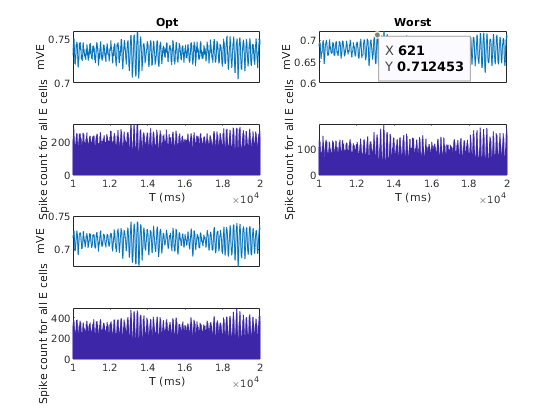


% Check soome time dependency
Opt = find(OD_E==1);
Worst = find(OD_E==3);
Nor = find(OD_E==2 | OD_E==4);

figure('Name','Theta')
subplot 423
hist(SpE(ismember(SpE(:,1),Opt),2),T:1:T+T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
subplot 421
plot(nanmean(mVE(OD_E'==1,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Opt')

subplot 424
hist(SpE(ismember(SpE(:,1),Worst),2),T:1:T+T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
subplot 422
plot(nanmean(mVE(OD_E'==3,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Worst')

subplot 427
hist(SpE(ismember(SpE(:,1),Nor),2),T:1:T+T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
subplot 425
plot(nanmean(mVE(OD_E'==2| OD_E'==4,:)))
ylabel('mVE')
set(gca,'xtick','')


OD_EMapTry = OD_EMap;
OD_EMapTry([1:54,109:161],:) = 0;
OD_EMapTry(:,[1:54,109:161]) = 0;
OptOne = find(OD_EMapTry(:)==1);
hist(SpE(ismember(SpE(:,1),OptOne),2),T:1:T+T)

Plot Spatial maps: Plot

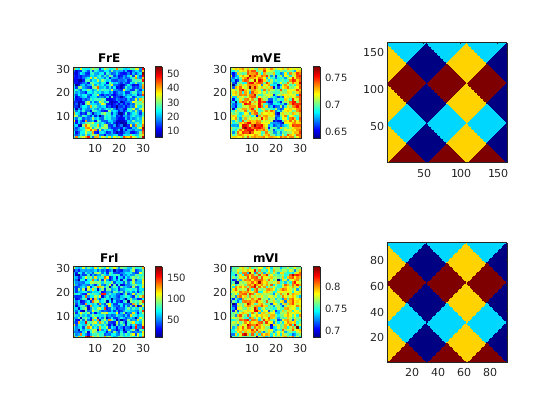

WinSize = 7500;
Window = [T+T-WinSize T+T];
EffSize = Window(2)-max(0,Window(1));

h = figure('Name','Field_f&V');

% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

subplot 231
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

[FrEPixMat,NnEPixel] = NeuVec2Pixel(FrE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window-T)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 232
mVE_temp = nanmean(mVE(:,SmallWinRange),2);
mVE_Map = reshape(mVE_temp,N_HC*n_E_HC,N_HC*n_E_HC);

[mVEPixMat,~] = NeuVec2Pixel(mVE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(mVEPixMat); title('mVE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 233
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')


% end of 500ms plot

    


%save('DriveWkSp.mat')

## MF linear equation for pixels: 1 Matrices

FrEPixVec = reshape(FrEPixMat,NPixX*N_HC*NPixY*N_HC,1);
FrIPixVec = reshape(FrIPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVEPixVec = reshape(mVEPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVIPixVec = reshape(mVIPixMat,NPixX*N_HC*NPixY*N_HC,1);
% First, get connectivity matrix between Pixels
C_EE_Pixel = zeros(length(FrEPixVec));
C_EI_Pixel = zeros(length(FrEPixVec));
C_IE_Pixel = zeros(length(FrEPixVec));
C_II_Pixel = zeros(length(FrEPixVec));
% look into std as well
C_EE_Pixelstd = zeros(length(FrEPixVec));
C_EI_Pixelstd = zeros(length(FrEPixVec));
C_IE_Pixelstd = zeros(length(FrEPixVec));
C_II_Pixelstd = zeros(length(FrEPixVec));
tic
AA = length(FrEPixVec);
parfor PixIndPost = 1:AA
    for PixIndPre = 1:AA
        C_EE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EE(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EI(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_IE(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixel(PixIndPost,PixIndPre) = mean(sum(C_II(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_EE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EE(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EI(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_IE(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_II(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
    end    
end
toc

Elapsed time is 2.117055 seconds.


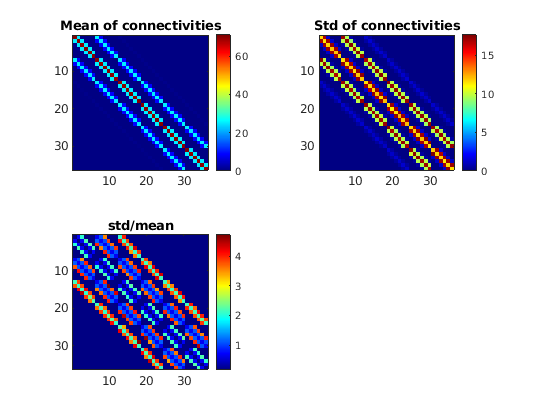

C_EE_Pixel_Us = sparse(C_EE_Pixel);
C_IE_Pixel_Us = sparse(C_IE_Pixel);
C_EI_Pixel_Us = sparse(C_EI_Pixel);
C_II_Pixel_Us = sparse(C_II_Pixel);

% Present connectivity mats
figure
subplot 221
imagesc(C_EE_Pixel)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_EE_Pixelstd)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_EE_Pixelstd./C_EE_Pixel)
axis square
colorbar
title('std/mean')

MF linear equation for pixels: 2 MF Eqns

% Mats
MatEE = (S_EE*(1-p_EEFail))*C_EE_Pixel_Us.*(Ve-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC)); % Need Ref here??
MatEI = S_EI *              C_EI_Pixel_Us.*(Vi-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatIE = S_IE *              C_IE_Pixel_Us.*(Ve-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatII = S_II *              C_II_Pixel_Us.*(Vi-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
ConnMat = [MatEE,MatEI;MatIE,MatII];
% Leak
LeakE = gL_E * (0-mVEPixVec) * 1e3;
LeakI = gL_I * (0-mVIPixVec) * 1e3;
LeakV = [LeakE;LeakI];
% Ext
lambda_E_Pixel = zeros(size(mVEPixVec));
for PixInd = 1:length(FrEPixVec)
    lambda_E_Pixel(PixInd) = mean(lambda_E_drive(NnEPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive;
ExtE = (lambda_E_Pixel*S_Elgn + rE_amb*S_amb + rE_L6*S_EL6).*(Ve-mVEPixVec) * 1e3;
ExtI = (lambda_I_Pixel*S_Ilgn + rI_amb*S_amb + rI_L6*S_IL6) *(Ve-mVIPixVec) * 1e3;
ExtV = [ExtE;ExtI];
% Ref Vec
RefE = 1-FrEPixVec*tau_ref/1e3;
RefI = 1-FrIPixVec*tau_ref/1e3;
RefM = sparse(diag([RefE;RefI]));
% L4 Frs
Fr_L4 = [FrEPixVec;FrIPixVec];

% MF Equations:
Fr_MF = RefM * (ConnMat*Fr_L4 + ExtV + LeakV);
Fr_MFinv = (sparse(eye(2*NPixX*N_HC*NPixY*N_HC))-RefM*ConnMat)^-1 * (RefM * ( ExtV + LeakV));

% Err
FrErr = Fr_MFinv - Fr_L4;

figure('Name','MF and Real Fr')
a1 = subplot (241);
PS = get(a1,'Position');
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a1,'Position',PS)

a5 = subplot (245);
PS = get(a5,'Position');
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a5,'Position',PS)

a2 = subplot (242);
PS = get(a2,'Position');
FrEPixMat_MF = reshape(Fr_MFinv(1:length(FrEPixVec)),NPixY*N_HC,NPixX*N_HC)

FrEPixMat_MF =    10.8440   14.8965   14.4445   10.0045   11.6416   14.9150
   11.5041   12.6092   11.4673   11.5799   10.9750   12.3119
   11.0857   13.5012   13.7901    9.9272   11.1877   13.5877
    9.2629   12.3839   11.6413   13.7116   11.9432   14.6841
   10.9944   15.0122   16.4398   13.4369   10.4827   13.5855
   11.0224   13.8373   13.7270   11.0322    9.7631   17.9781


imagesc(FrEPixMat_MF); title('FrE_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a2,'Position',PS)

a6 = subplot (246);
PS = get(a6,'Position');
FrIPixMat_MF = reshape(Fr_MFinv(length(FrEPixVec)+1:end),NPixY*N_HC,NPixX*N_HC)

FrIPixMat_MF =    31.3920   38.6719   38.3743   32.5089   33.9974   36.8442
   33.9091   40.3324   38.4568   35.0897   37.4059   35.9893
   33.9103   39.2825   39.3966   35.5830   36.6411   36.4371
   30.2113   38.6368   40.5581   40.0116   38.3306   38.6274
   33.9003   43.6677   45.3750   40.7425   36.7293   39.4789
   31.3627   38.0439   39.5614   32.4936   32.8932   39.6958


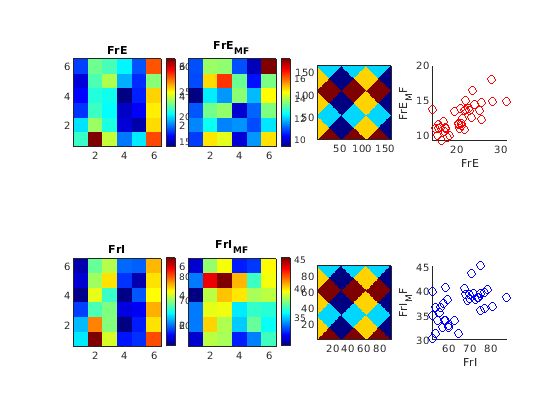

imagesc(FrIPixMat_MF); title('FrI_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a6,'Position',PS)

subplot 243
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 247
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

subplot 244
scatter(FrEPixVec,Fr_MFinv(1:NPixX*N_HC*NPixY*N_HC),'ro')
% axis([0 40 0 40])
axis square
xlabel('FrE'); ylabel('FrE_MF')

subplot 248
scatter(FrIPixVec,Fr_MFinv(NPixX*N_HC*NPixY*N_HC+1:end),'bo')
% axis([0 120 0 120])
axis square
xlabel('FrI'); ylabel('FrI_MF')

Result not very good. On the other hand, should concern real input since we are only averaging from 25/8 neurons?

Check code: Mistakes in row and column?